## LSTM 

### Import the hourly RMSE and MAPE for AC and DC load

clear
load('LSTM_AC')
load('LSTM_DC')

%load('NN_AC')
%load('NN_DC')

#### Plot Root Mean Square Error

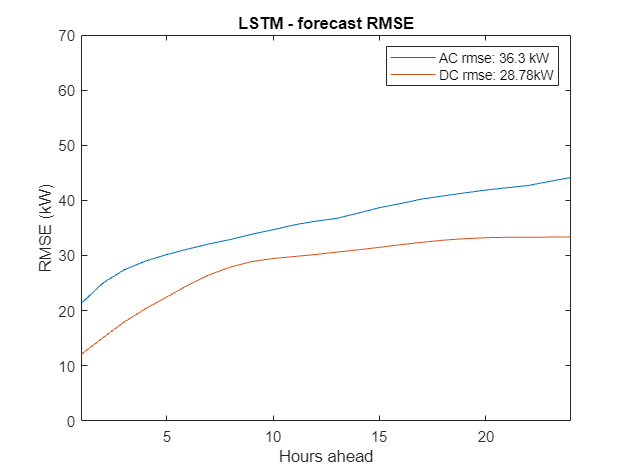

figure
        plot(1:24,hourlyACrmse);
        hold on
        plot(1:24,hourlyDCrmse);
        hold off
        legend("AC rmse: "+ round(ACrmseMean,2)+" kW", "DC rmse: "+ round(DCrmseMean,2)+"kW")
        title("LSTM - forecast RMSE")
        xlabel("Hours ahead")
        xlim([1 24]);
        ylim([0 70]);
        ylabel("RMSE (kW)")


ax = gca;
chart = ax.Children(2);


#### Plot Mean Absolute Percentage error

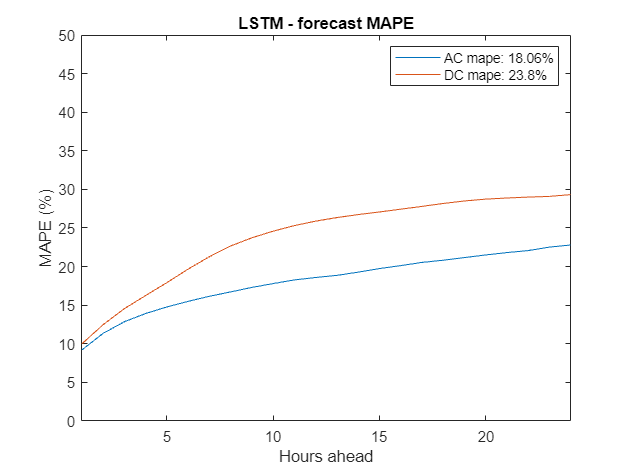

figure
        plot(1:24, hourlyACmape);
        hold on
        plot(1:24,hourlyDCmape);
        hold off
        legend("AC mape: " + round(mean(hourlyACmape),2) + "%", "DC mape: "+ round(mean(hourlyDCmape),2)+"%")
        title("LSTM - forecast MAPE")
        xlabel("Hours ahead")
        xlim([1 24]);
        ylim([0 50]);
        ylabel("MAPE (%)")



        display("AC  1 step ahead MAPE: " + hourlyACmape(1)+"%")

    "AC  1 step ahead MAPE: 9.1819%"



        display("AC  1 step ahead RMSE: " + hourlyACrmse(1)+" kW")

    "AC  1 step ahead RMSE: 21.4154 kW"



        display("DC  1 step ahead MAPE: " + hourlyDCmape(1)+"%")

    "DC  1 step ahead MAPE: 9.9731%"



        display("DC  1 step ahead RMSE: " + hourlyDCrmse(1)+" kW")

    "DC  1 step ahead RMSE: 12.148 kW"



        
        display("AC int Mape: " + ACintMape + "%")

    "AC int Mape: 11.424%"



        display("AC int RMSE: " + ACintRmse + "kW")

    "AC int RMSE: 21.8978kW"



        display("AC total int RMSE: " + ACtotalIntRmse + "kW")

    "AC total int RMSE: 525.548kW"



        display("DC int Mape: " + DCintMape + "%")

    "DC int Mape: 18.6706%"



        display("DC int RMSE: " + DCintRmse + "kW")

    "DC int RMSE: 18.1838kW"



        display("DC total int RMSE: " + DCtotalIntRmse + "kW")

    "DC total int RMSE: 436.4116kW"





        display("AC MAPE: " + mean(hourlyACmape)+"%")

    "AC MAPE: 18.0572%"



        display("AC RMSE: " +ACrmseMean+" kW")

    "AC RMSE: 36.2976 kW"



        display("DC MAPE: " + mean(hourlyDCmape)+"%")

    "DC MAPE: 23.8033%"



        display("DC RMSE: " + DCrmseMean+" kW")

    "DC RMSE: 28.7832 kW"



## SARIMA Results

load('SARIMA_AC')
load('SARIMA_DC')

#### Plot Root Mean Square Error

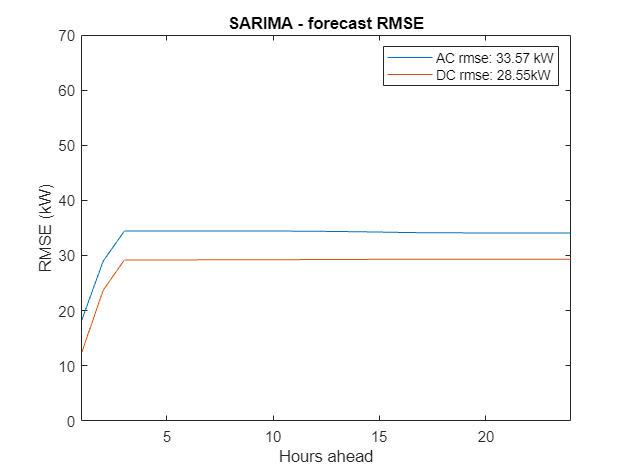

figure
        plot(1:24,hourlyACrmse);
        hold on
        plot(1:24,hourlyDCrmse);
        hold off
        legend("AC rmse: "+ round(ACrmseMean,2)+" kW", "DC rmse: "+ round(DCrmseMean,2)+"kW")
        title("SARIMA - forecast RMSE")
        xlim([1 24]);
        ylim([0 70]);
        xlabel("Hours ahead")
        ylabel("RMSE (kW)")

#### Plot Mean Absolute Percentage error

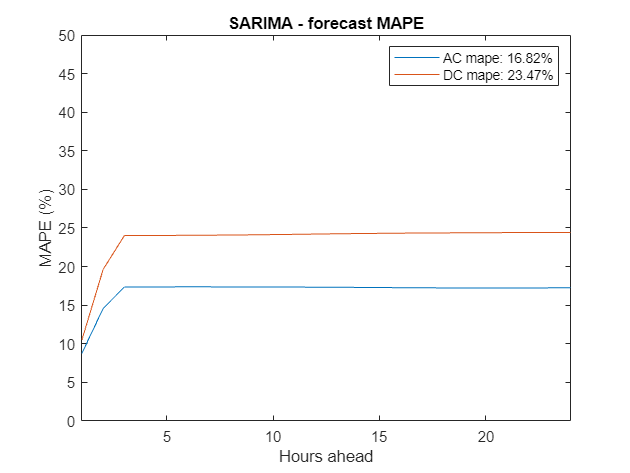

figure
        plot(1:24, hourlyACmape);
        hold on
        plot(1:24,hourlyDCmape);
        hold off
        legend("AC mape: " + round(mean(hourlyACmape),2) + "%", "DC mape: "+ round(mean(hourlyDCmape),2)+"%")
        title("SARIMA - forecast MAPE")
        xlim([1 24]);
        ylim([0 50]);
        xlabel("Hours ahead")
        ylabel("MAPE (%)")



        display("AC  1 step ahead MAPE: " + hourlyACmape(1)+"%")

    "AC  1 step ahead MAPE: 8.7436%"



        display("AC  1 step ahead RMSE: " +hourlyACrmse(1)+" kW")

    "AC  1 step ahead RMSE: 18.3123 kW"



        display("DC  1 step ahead MAPE: " + hourlyDCmape(1)+"%")

    "DC  1 step ahead MAPE: 10.4678%"



        display("DC  1 step ahead RMSE: " + hourlyDCrmse(1)+" kW")

    "DC  1 step ahead RMSE: 12.4588 kW"



        
        display("AC int Mape: " + ACintMape + "%")

    "AC int Mape: 11.0485%"



        display("AC int RMSE: " + ACintRmse + "kW")

    "AC int RMSE: 20.8132kW"



        display("AC total int RMSE: " + ACtotalIntRmse + "kW")

    "AC total int RMSE: 499.5167kW"



        display("DC int Mape: " + DCintMape + "%")

    "DC int Mape: 22.0021%"



        display("DC int RMSE: " + DCintRmse + "kW")

    "DC int RMSE: 19.131kW"



        display("DC total int RMSE: " + DCtotalIntRmse + "kW")

    "DC total int RMSE: 459.1438kW"



        
        display("AC MAPE: " + mean(hourlyACmape)+"%")

    "AC MAPE: 16.8199%"



        display("AC RMSE: " +ACrmseMean+" kW")

    "AC RMSE: 33.5677 kW"



        display("DC MAPE: " + mean(hourlyDCmape)+"%")

    "DC MAPE: 23.4651%"



        display("DC RMSE: " + DCrmseMean+" kW")

    "DC RMSE: 28.5531 kW"



## Neural Net Results

load('NN_AC')
load('NN_DC')


#### Plot Root Mean Square Error

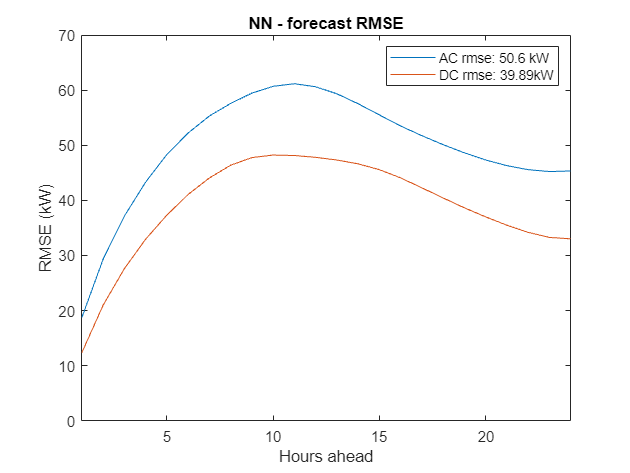

figure
        plot(1:24,hourlyACrmse);
        hold on
        plot(1:24,hourlyDCrmse);
        hold off
        legend("AC rmse: "+ round(ACrmseMean,2)+" kW", "DC rmse: "+ round(DCrmseMean,2)+"kW")
        title("NN - forecast RMSE")
        xlim([1 24]);
        ylim([0 70]);
        xlabel("Hours ahead")
        ylabel("RMSE (kW)")

#### Plot Mean Absolute Percentage error

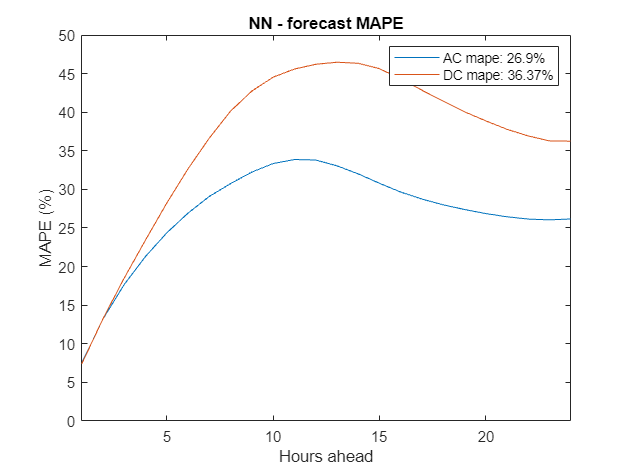

figure
        plot(1:24, hourlyACmape);
        hold on
        plot(1:24,hourlyDCmape);
        hold off
        legend("AC mape: " + round(mean(hourlyACmape),2) + "%", "DC mape: "+ round(mean(hourlyDCmape),2)+"%")
        title("NN - forecast MAPE")
        xlabel("Hours ahead")
        ylabel("MAPE (%)")
        xlim([1 24]);
        ylim([0 50]);



        display("AC  1 step ahead MAPE: " + hourlyACmape(1)+"%")

    "AC  1 step ahead MAPE: 7.5188%"



        display("AC  1 step ahead RMSE: "   + hourlyACrmse(1)+" kW")

    "AC  1 step ahead RMSE: 18.7522 kW"



        display("DC  1 step ahead MAPE: " + hourlyDCmape(1)+"%")

    "DC  1 step ahead MAPE: 7.3978%"



        display("DC  1 step ahead RMSE: " + hourlyDCrmse(1)+" kW")

    "DC  1 step ahead RMSE: 12.3745 kW"



        
        display("AC int Mape: " + ACintMape + "%")

    "AC int Mape: 14.6902%"



        display("AC int RMSE: " + ACintRmse + "kW")

    "AC int RMSE: 26.5501kW"



        display("AC total int RMSE: " + ACtotalIntRmse + "kW")

    "AC total int RMSE: 637.202kW"



        display("DC int Mape: " + DCintMape + "%")

    "DC int Mape: 25.4569%"



        display("DC int RMSE: " + DCintRmse + "kW")

    "DC int RMSE: 23.5186kW"



        display("DC total int RMSE: " + DCtotalIntRmse + "kW")

    "DC total int RMSE: 564.4471kW"




        display("AC MAPE: "     + mean(hourlyACmape)+"%")

    "AC MAPE: 26.898%"



        display("AC RMSE: "     + ACrmseMean+" kW")

    "AC RMSE: 50.6032 kW"



        display("DC MAPE: "     + mean(hourlyDCmape)+"%")

    "DC MAPE: 36.3723%"



        display("DC RMSE: "     + DCrmseMean+" kW")

    "DC RMSE: 39.8875 kW"

